# №1 a)

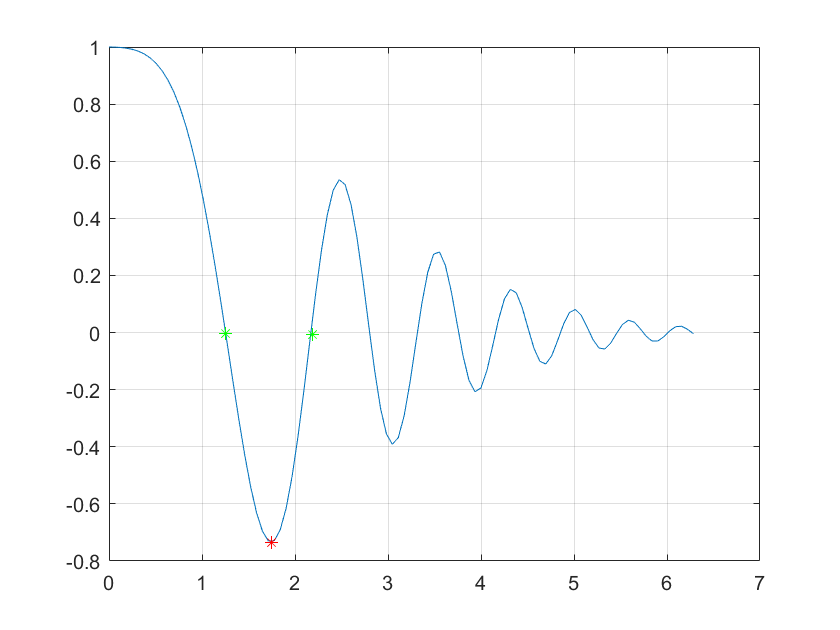

phi = 0.1;
a = 0; b = 2*pi;
x = linspace(a,b,100);
y = exp(-1*phi.*x.*x).*cos(x.*x);
Y = @(x)exp(-1*phi.*x.*x).*cos(x.*x);
plot(x,y);
grid on;
xr = ginput(2);
[x_m,y_m] = fminbnd(Y,xr(1,1),xr(2,1));
hold on;
plot(x_m,y_m,'r*',xr(1,1),xr(1,2),'g*',xr(2,1),xr(2,2),'g*');
hold off;

## №1 b)

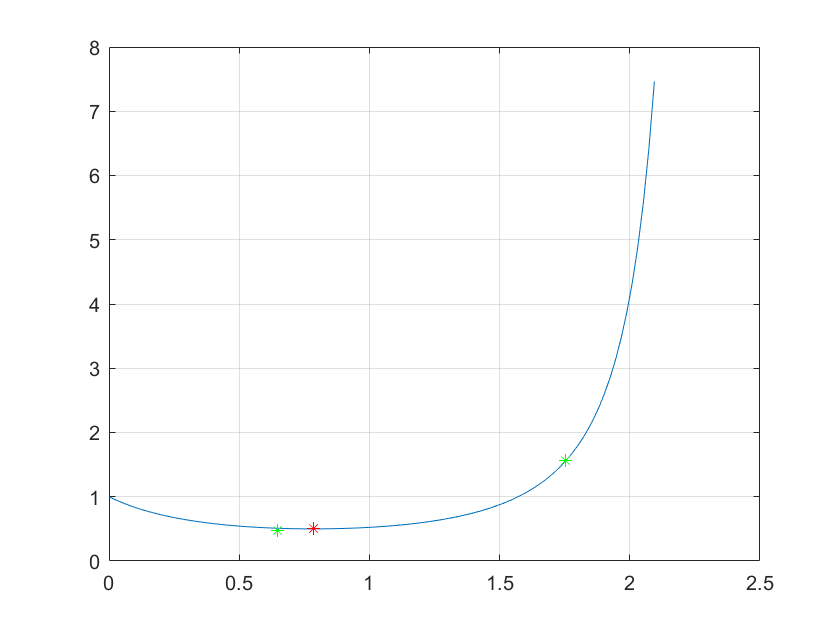

a1 = 1; b1 = 1;
a = 0; b = 2*pi/3;
x = linspace(a,b,100);
y = 1./(a1*cos(x)+b1*sin(x)).^2;
Y = @(x)1./(a1*cos(x)+b1*sin(x)).^2;
plot(x,y);
grid on;
xr = ginput(2);
[x_m,y_m] = fminbnd(Y, xr(1,1), xr(2,1));
hold on;
plot(x_m,y_m,'r*',xr(1,1),xr(1,2),'g*',xr(2,1),xr(2,2),'g*');
hold off;

## №2 a)

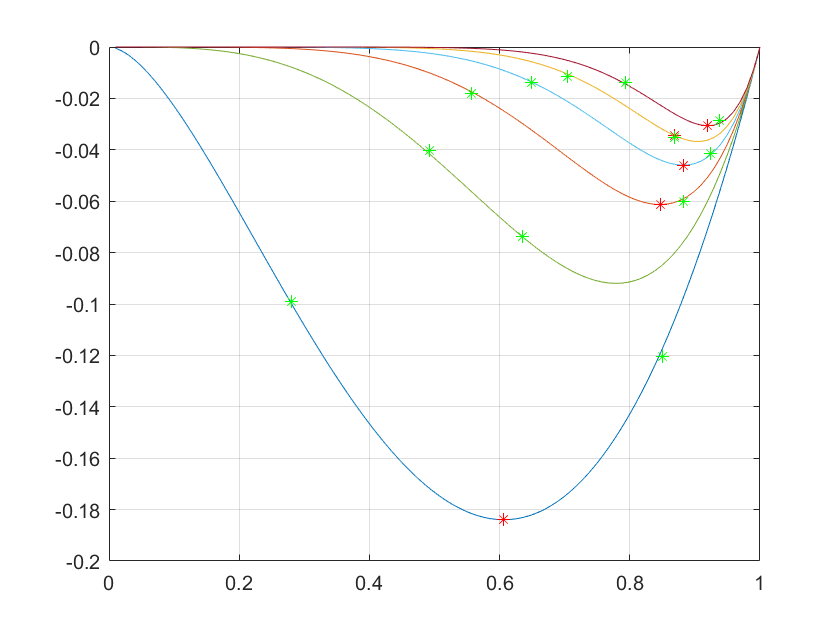

a = 0; b = 1;
x = linspace(a,b,100);
for alpha=2:2:12
    y = x.^alpha.*log(x);
    Y = @(x)x.^alpha.*log(x);
    plot(x,y);
    grid on;
    xr = ginput(2);
    [x_m,y_m] = fminbnd(Y, xr(1,1), xr(2,1));
    hold on;
    plot(x_m,y_m,'r*',xr(1,1),xr(1,2),'g*',xr(2,1),xr(2,2),'g*');
end